**UNIDAD: MÉTODO DEL TRABAJO VIRTUAL**

**PROBLEMA 1**

La barra mostrada en la Fig. 1.1, cuya masa es de 100 kg, está apoyada sobre superficies lisas en $A$ y $B$. Desarrollar lo siguiente:

- Mediante equilibrio de fuerzas, determinar $F$, y las reacciones $A_x$ y $B_y$ en $A$ y $B$, respectivamente.

- Mediante el método del trabajo virtual, determinar el valor de $F$ que mantiene a la barra en equilibrio.

- Mediante el método del trabajo virtual, determinar la reacción $B_y$.

- Mediante el método del trabajo virtual, determinar la reacción $A_x$.

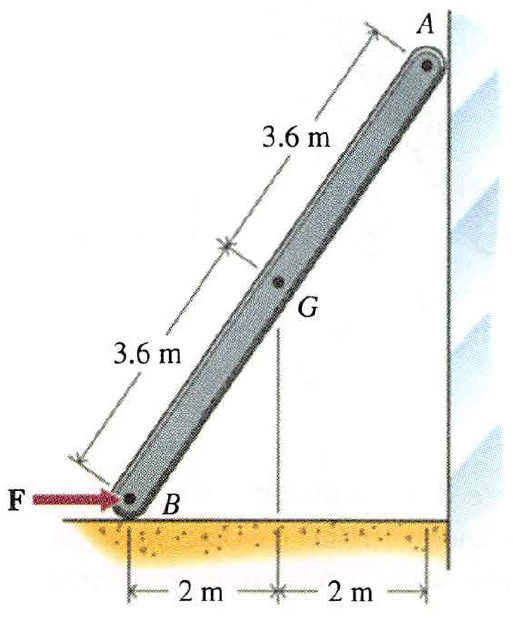

Fig. 1.1: Barra apoyada sobre superficies lisas.

**SOLUCIÓN**

1.  Mediante equilibrio de fuerzas, determinar $F$, y las reacciones $A_x$ y $B_y$ en $A$ y $B$, respectivamente.

La Fig. 1.2 muestra el diagrama de cuerpo libre de la barra. 

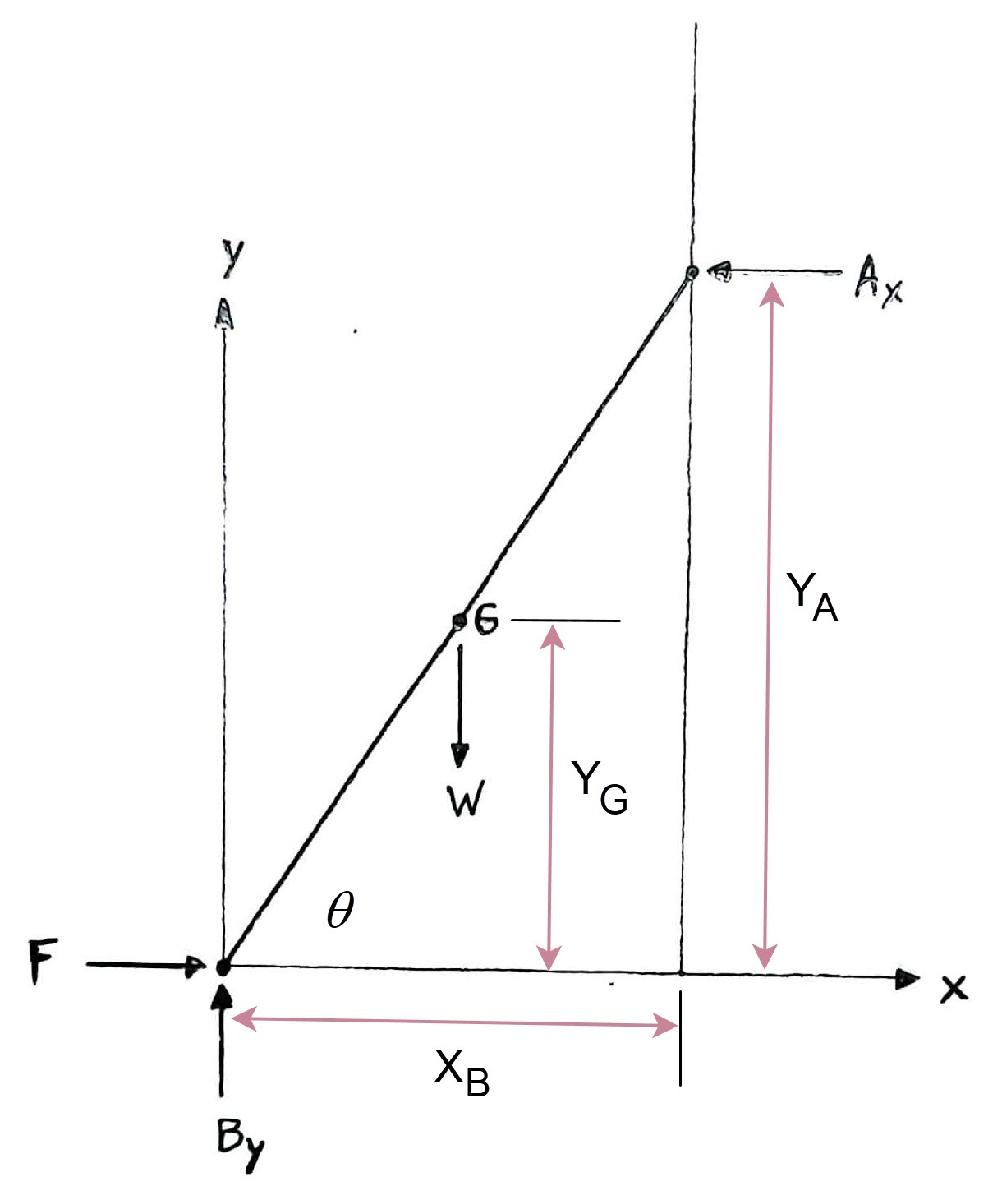

Fig. 1.2: Diagrama de cuerpo libre de la barra.

El equilibrio de fuerzas es el siguiente:


$$\sum F_x=0: \quad\quad F-A_x=0\\
\sum F_y=0: \quad\quad B_y-W=0\\
\sum M_B=0: \quad\quad A_x\sqrt{(3.6+3.6)^2-(2+2)^2}-W\,(3.6\cos\theta)=0, \quad \cos\theta=\frac{2}{3.6}.$$


Resolvemos estas ecuaciones:

M = 100; % masa de la barra
a = 2; % distancia horizontal entre B y G, y G y A
b = 3.6; % distancia total entre B y G, y G y A
W = M*9.81; % peso de la barra
cost = a/b;
Ax = W*b*cost/sqrt((b+b)^2-(a+a)^2);
F = Ax;
By = W;

Resultados:

fprintf('Ax = %.2f N\n',Ax);

Ax = 327.73 N


fprintf('By = %.2f N\n',By);

By = 981.00 N


fprintf('F = %.2f N\n',F);

F = 327.73 N


2. Mediante el método del trabajo virtual, determinar el valor de $F$ que mantiene a la barra en equilibrio.

Para determinar la fuerza $F$ se impone un desplazamiento virtual horizontal en $B$, el que puede ser en el sentido de $F$ o en sentido opuesto. Se elige imponerlo en el sentido opuesto. Esto produce el movimiento virtual mostrado en la Fig. 1.3.

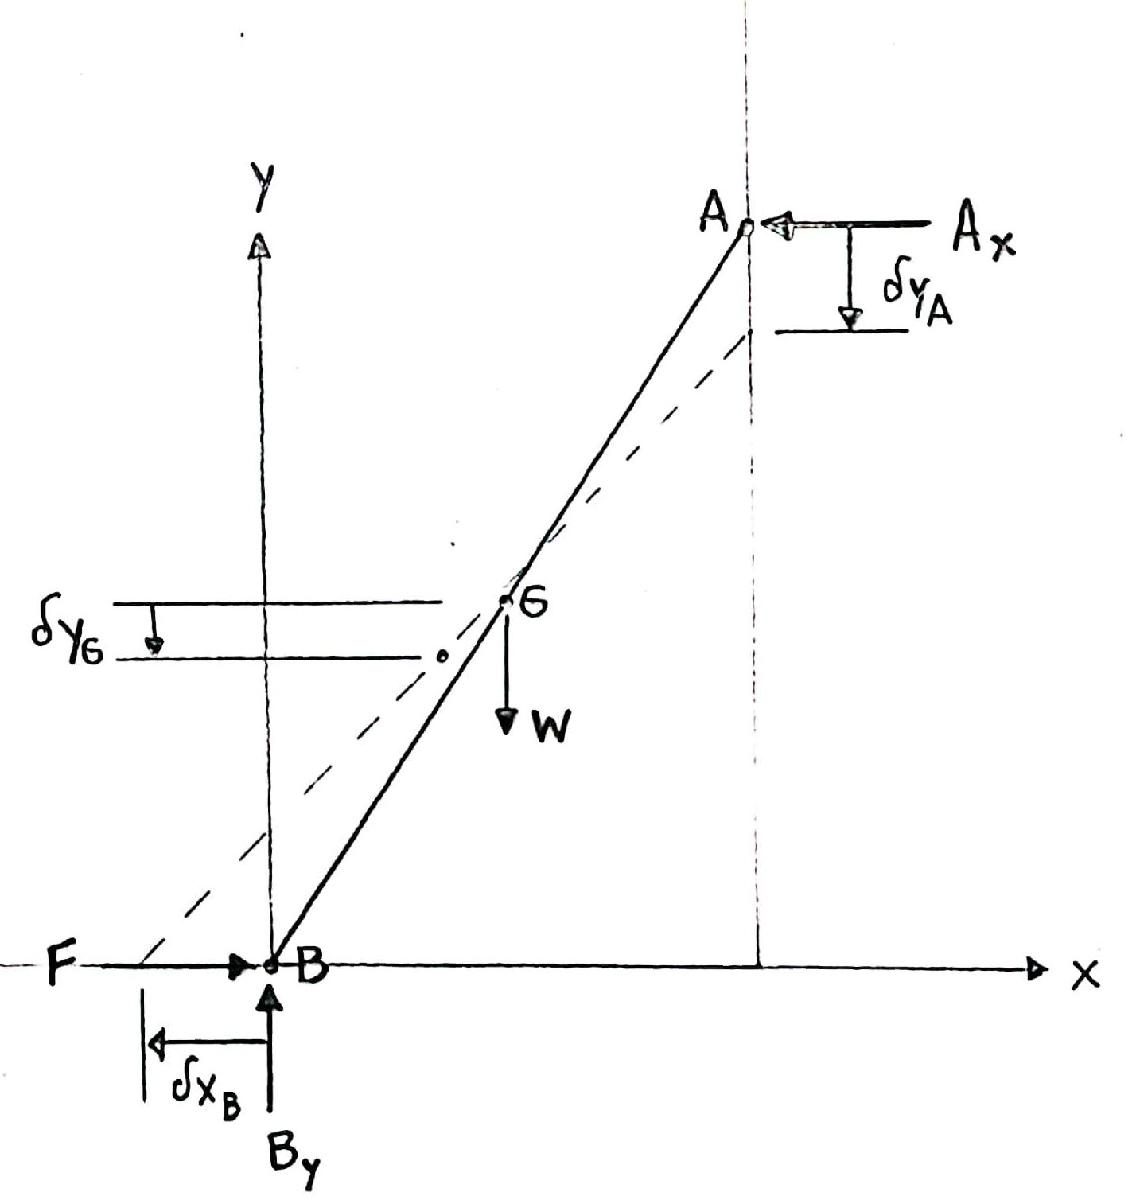

Fig. 1.3: Desplazamientos virtuales impuestos en la barra.

Solo producen trabajo virtual las fuerzas que están en la dirección de los desplazamientos virtuales. 

Solo las fuerzas $F$ y $W$ producen trabajo virtual. Igualando a cero el trabajo virtual total, se obtiene


$$\delta U=-F\,\delta x_B+W\,\delta y_G=0.$$


Utilizando relaciones geométricas, se obtienen los siguientes desplazamientos virtuales:


$$x_B=(3.6+3.6)\cos\theta \Rightarrow \delta x_B=-(3.6+3.6)\sin\theta\,\delta\theta\\
y_G=3.6\sin\theta \Rightarrow \delta y_G=3.6\cos\theta\,\delta\theta.$$


Dado que los signos de los trabajos virtuales ya fueron considerados en $\delta U$, se consideran solo los valores absolutos de los desplazamientos virtuales calculados. Por lo tanto,


$$\delta U=-F\,(3.6+3.6)\sin\theta\,\delta\theta+W\,3.6\cos\theta\,\delta\theta=0,$$


y dado que $\delta\theta\neq 0$, se obtiene


$$-F\,(3.6+3.6)\sin\theta+W\,3.6\cos\theta=0,  \quad \cos\theta=\frac{2}{3.6}, \quad \sin\theta=\frac{\sqrt{3.6^2-2^2}}{3.6}.$$


Resolvemos esta ecuación:

sint = sqrt(b^2-a^2)/b;
F = W*b*cost/((b+b)*sint);
fprintf('F = %.2f N\n',F);

F = 327.73 N


3. Mediante el método del trabajo virtual, determinar la reacción $B_y$.

Para determinar $B_y$ se imponen los desplazamientos virtuales que se muestran en la Fig. 1.4.

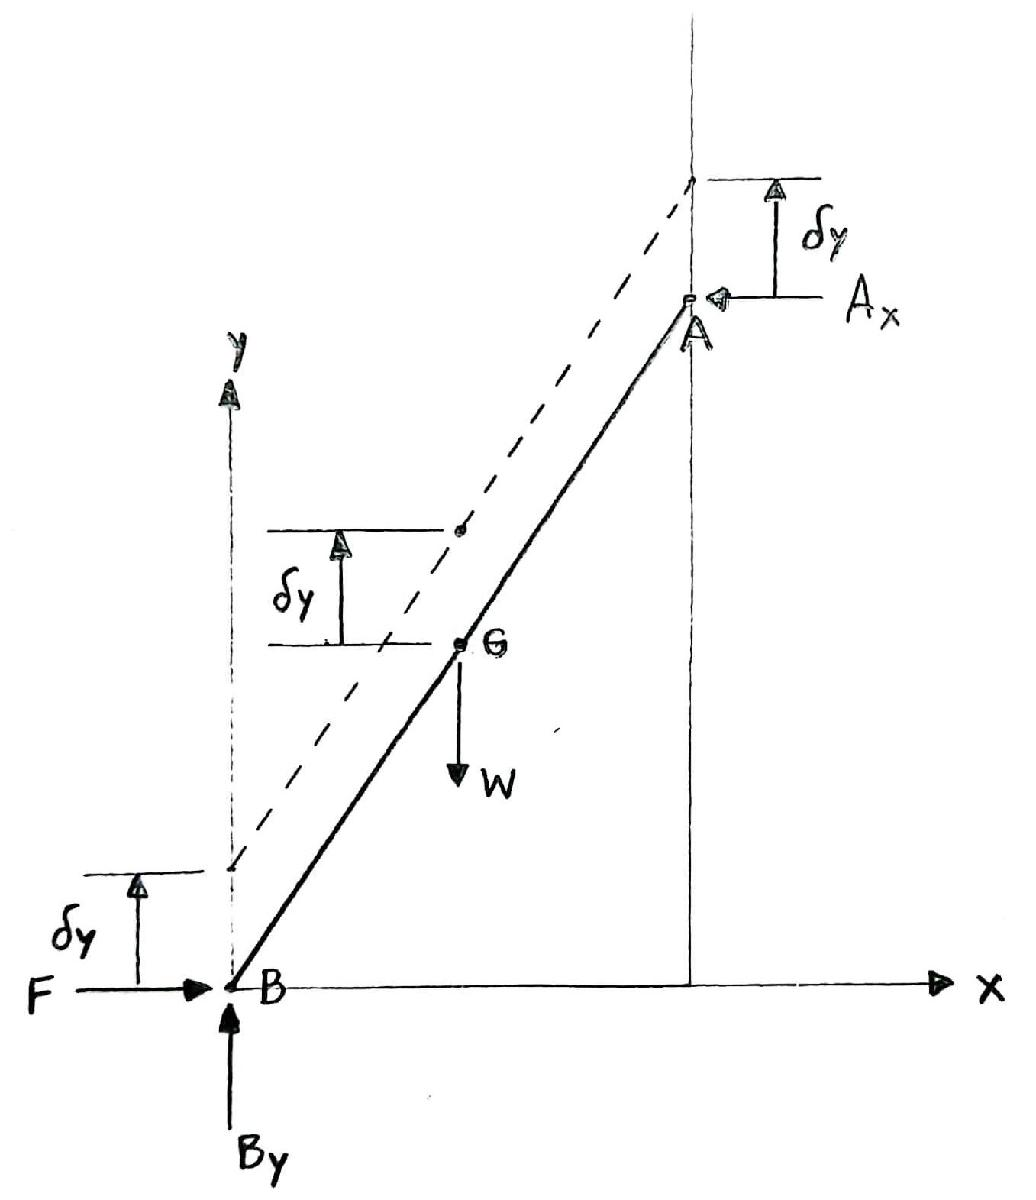

Fig. 1.4: Desplazamientos virtuales impuestos en la barra.

En este caso, solo producen trabajo virtual las fuerzas $B_y$ y $W$. Igualando a cero el trabajo virtual total, se obtiene


$$\delta U=B_y\,\delta y-W\,\delta y=0.$$


Dado que $\delta y \neq 0$, se obtiene


$$B_y-W=0.$$


Resolviendo $B_y$, se obtiene

By = W;
fprintf('By = %.2f N\n',By);

By = 981.00 N


4. Mediante el método del trabajo virtual, determinar la reacción $A_x$.

Para determinar $A_x$ se imponen los desplazamientos virtuales que se muestran en la Fig. 1.5.

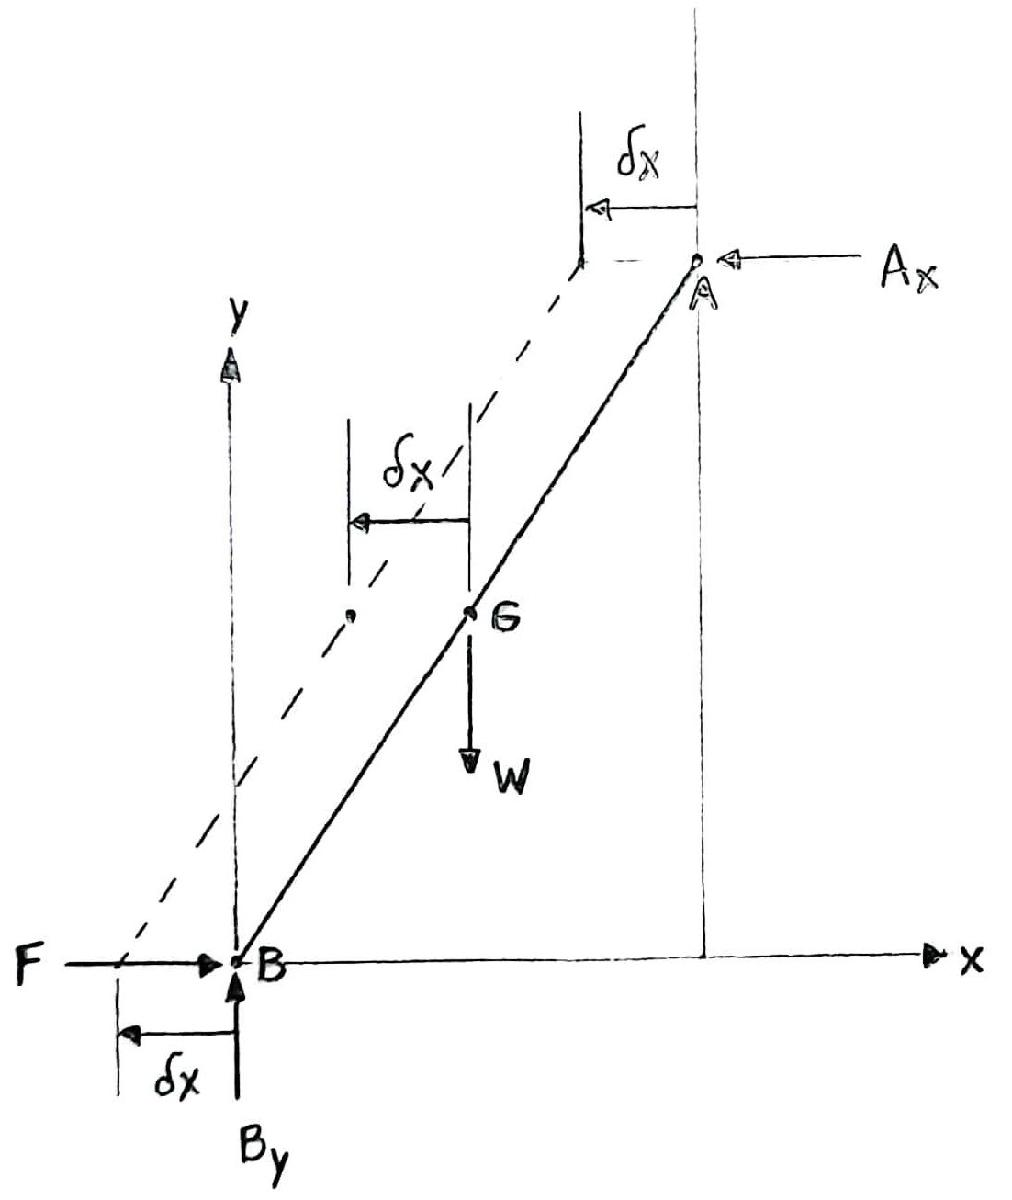

Fig. 1.5: Desplazamientos virtuales impuestos en la barra.

En este caso, solo producen trabajo virtual las fuerzas $A_x$ y $F$. Igualando a cero el trabajo virtual total, se obtiene


$$\delta U=A_x\,\delta x-F\,\delta x=0.$$


Dado que $\delta x\neq 0$, se obtiene


$$A_x-F=0.$$


Resolviendo $A_x$ (y usando el valor de $F$ ya encontrado mediante el método del trabajo virtual) , se obtiene

Ax = F;
fprintf('Ax = %.2f N\n',Ax);

Ax = 327.73 N


**OBTENER ARCHIVO MATLAB LIVE:**  [U6_problema1.mlx](https://github.com/CAMLAB-UChile/ME3130/blob/e0cd9e2ab7a2a88ab1a9cb3df72a4cb55b36a155/Unidad6/U6_problema1.mlx)